# 実験Ⅳ－１　`多項式回帰モデル`

`新潟大学工学部工学科　電子情報通信プログラム `

- `サンプルデータの読み込み`

- `線形単回帰の実行`

- `多項式単回帰の実行`

## `ファイルを読み込む`

`以下の方法があります。`

- `ファイルをアップロードする`

- `URL を指定する`

% 観測データのファイル
filename = 'https://raw.githubusercontent.com/msiplab/EicEngLabIV/master/data/sample01_01.csv';

% 観測データ（空白区切り）の読み込み
dataset = readtable(filename);

% データの表示
disp(dataset)

      XDATA         YDATA   
    _________    ___________

     0.069302       0.070821
     0.076557      -0.013583
      0.80022        0.97184
       0.5587        0.77368
      0.77122        0.98634
     0.089858      0.0062672
     0.077151       0.073523
      0.76882        0.99969
      0.71629           1.01
      0.47481        0.40587
      0.80556        0.98865
      0.88414        0.98659
     0.041922      -0.083773
       0.6963         1.0673
      0.24667     -0.0023917
      0.63109        0.92316
       0.7413        0.97982
     0.025565       0.037283
      0.29646       0.037773
      0.96544        0.98282
      0.96825        0.99324
      0.32474        0.04629
      0.86572        0.97346
      0.53865        0.79126
      0.44604         0.2647
      0.47142        0.33177
      0.54246        0.77546
      0.58323        0.73081
       0.9158         1.0012
      0.24572        0.02394
      0.86884          0.961
     0.024023      -0.057223
      0.99981


% 観測データ数
nSamples = height(dataset)

nSamples = 200

% 説明変数の設定
x = dataset.XDATA;
disp(x)

    0.0693
    0.0766
    0.8002
    0.5587
    0.7712
    0.0899
    0.0772
    0.7688
    0.7163
    0.4748
    0.8056
    0.8841
    0.0419
    0.6963
    0.2467
    0.6311
    0.7413
    0.0256
    0.2965
    0.9654
    0.9683
    0.3247
    0.8657
    0.5387
    0.4460
    0.4714
    0.5425
    0.5832
    0.9158
    0.2457
    0.8688
    0.0240
    0.9998
    0.9822
    0.4643
    0.4041
    0.9744
    0.4374
    0.0347
    0.2272
    0.5041
    0.0532
    0.0643
    0.3830
    0.3322
    0.8193
    0.8773
    0.6805
    0.6940
    0.2597
    0.5061
    0.1840
    0.4709
    0.3172
    0.3020
    0.4733
    0.8984
    0.5170
    0.8831
    0.1695
    0.3127
    0.6319
    0.7165
    0.9827
    0.8457
    0.9865
    0.8752
    0.1359
    0.6830
    0.2991
    0.1850
    0.4195
    0.8275
    0.4564
    0.0846
    0.0805
    0.0783
    0.2915
    0.6243
    0.4581
    0.1642
    0.5717
    0.2621
    0.4417
    0.2603
    0.7694
    0.8936
    0.8370
    0.3394
    0.5005
    0.8508


% 目的変数の設定
y = dataset.YDATA;
disp(y)

    0.0708
   -0.0136
    0.9718
    0.7737
    0.9863
    0.0063
    0.0735
    0.9997
    1.0100
    0.4059
    0.9886
    0.9866
   -0.0838
    1.0673
   -0.0024
    0.9232
    0.9798
    0.0373
    0.0378
    0.9828
    0.9932
    0.0463
    0.9735
    0.7913
    0.2647
    0.3318
    0.7755
    0.7308
    1.0012
    0.0239
    0.9610
   -0.0572
    0.9378
    1.0417
    0.3920
    0.0529
    0.9860
    0.3156
    0.0037
   -0.0780
    0.6019
   -0.0344
    0.0627
    0.0351
    0.0262
    0.9575
    1.0648
    0.9220
    0.9548
   -0.0193
    0.4626
    0.0457
    0.2770
   -0.0429
    0.0324
    0.3842
    0.9454
    0.6183
    0.9780
   -0.0440
    0.0580
    0.9106
    1.0298
    1.0702
    0.9258
    1.0250
    0.9166
    0.0564
    1.0013
   -0.0389
   -0.0007
    0.1393
    0.9919
    0.3158
    0.0546
   -0.0314
    0.0186
   -0.0131
    0.9471
    0.3193
    0.0816
    0.8395
   -0.0027
    0.1810
   -0.0257
    0.9563
    1.0357
    0.9953
    0.0417
    0.5688
    0.9700

## `観測データの散布図`

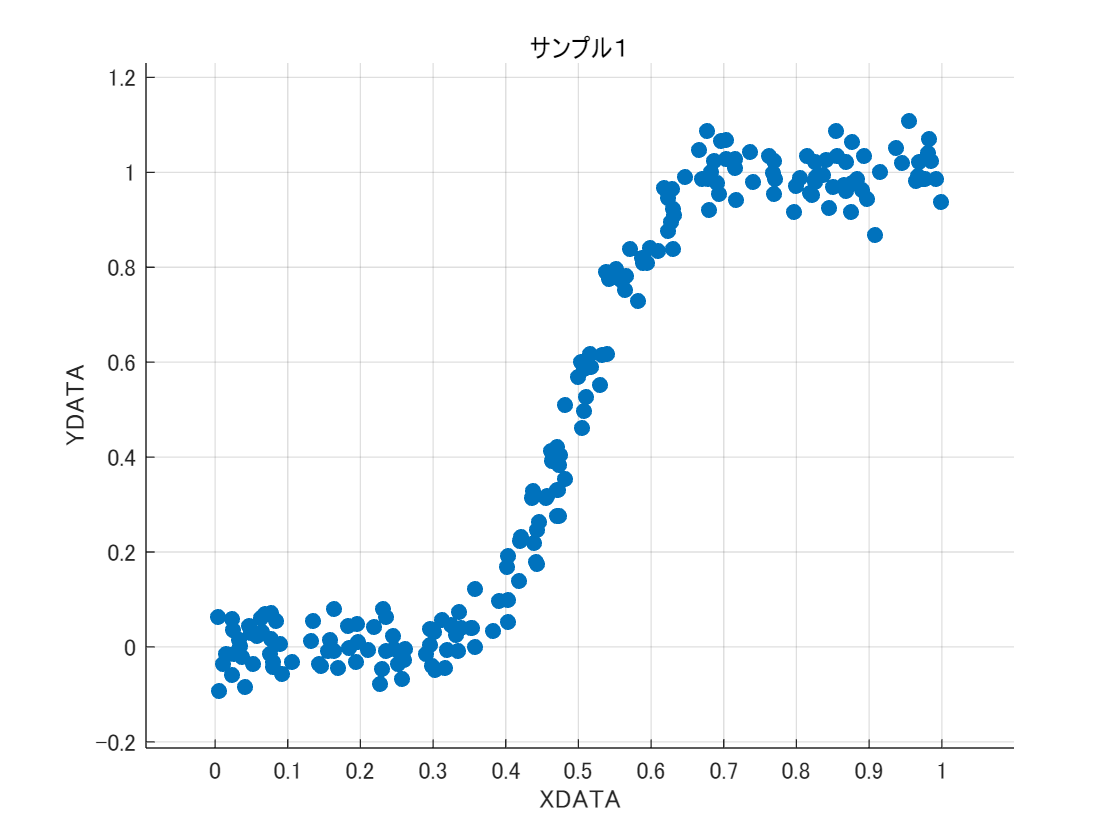

% 散布図の範囲情報の抽出
minx = min(x);
maxx = max(x);
rx = maxx-minx;
cx = 0.5*rx;
miny = min(y);
maxy = max(y);
ry = maxy-miny;
cy = 0.5*ry;

% 散布図の表示
figure
ax = gca;
scatter(x,y,'filled')
title("サンプル１")
xlabel(dataset.Properties.VariableNames{1})
ylabel(dataset.Properties.VariableNames{2})
ax.XLim = [minx-0.1*rx,maxx+0.1*rx];
ax.YLim = [miny-0.1*ry,maxy+0.1*ry];
grid on

drawnow

## `線形単回帰の実行`

% 線形単回帰分析
regu = fit(x,y,'poly1');

%  推定結果
beta0 = regu.p2;
beta1 =  regu.p1;
fprintf("β0 = %5.2f ",beta0)

β0 = -0.21 

fprintf("β1 = %5.2f",beta1)

β1 =  1.42

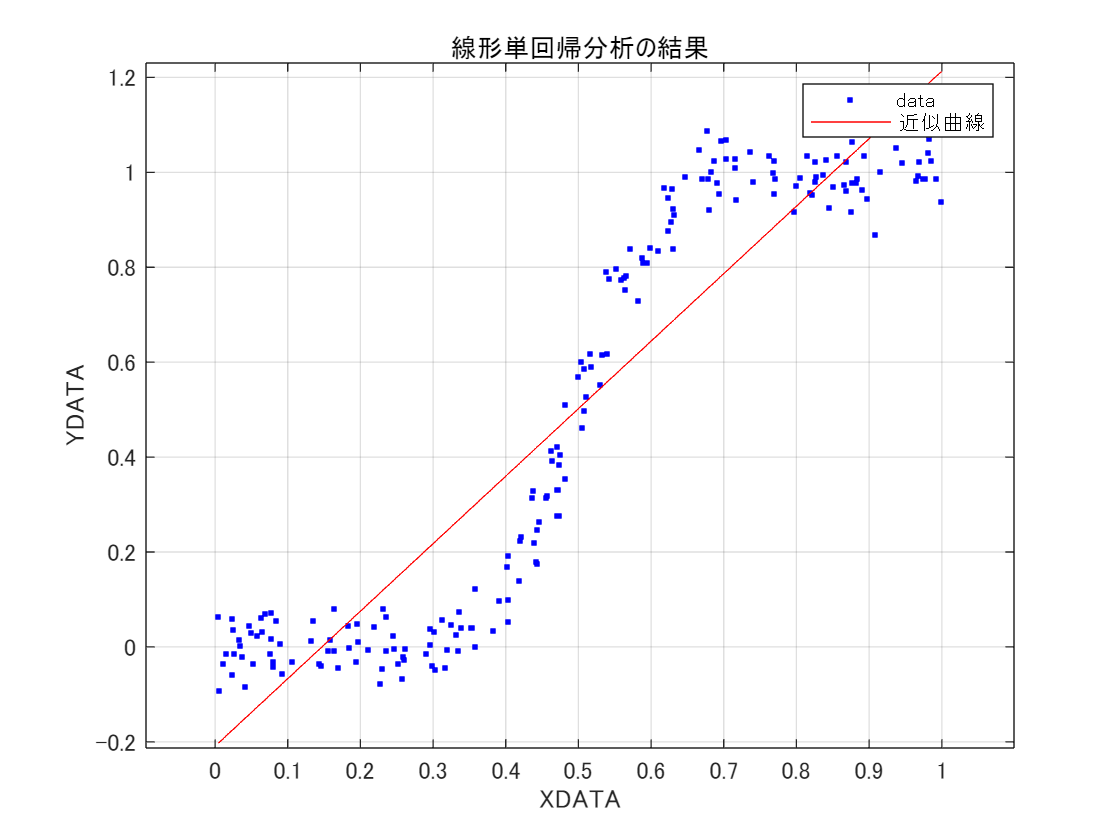

% 回帰直線をプロット
fig = figure;
ax = gca;
plot(regu,x,y)
title("線形単回帰分析の結果");
xlabel(dataset.Properties.VariableNames{1})
ylabel(dataset.Properties.VariableNames{2})
ax.XLim = [minx-0.1*rx,maxx+0.1*rx];
ax.YLim = [miny-0.1*ry,maxy+0.1*ry];
grid on

drawnow

## `多項式単回帰モデルの次数の選択`

% from sklearn.preprocessing import PolynomialFeatures
% from sklearn.pipeline import make_pipeline
% from sklearn.metrics import mean_squared_error
% 
maxdeg = 30;
aic = zeros(maxdeg,1);
regp = cell(maxdeg,1);
for deg = 1:maxdeg

    % 多項式単回帰分析
    regp{deg} = polyfit(x,y,deg);
    % [regp{deg},~,mu] = polyfit(x,y,deg); % センタリングとスケーリングを使用

    % AIC
    ypred = polyval(regp{deg},x);
    % ypred = polyval(regp{deg},x,[],mu); % センタリングとスケーリングを使用
    mse_ = mean((y-ypred).^2);
    aic(deg) = nSamples*log(2*pi*mse_)+nSamples+2*(deg+2);
    fprintf("deg = %d: AIC = %5.2e \n",deg,aic(deg))
end

deg = 1: AIC = -1.47e+02 
deg = 2: AIC = -1.46e+02 
deg = 3: AIC = -3.77e+02 
deg = 4: AIC = -3.75e+02 
deg = 5: AIC = -5.54e+02 
deg = 6: AIC = -5.52e+02 
deg = 7: AIC = -6.16e+02 
deg = 8: AIC = -6.16e+02 
deg = 9: AIC = -6.21e+02 
deg = 10: AIC = -6.21e+02 
deg = 11: AIC = -6.22e+02 
deg = 12: AIC = -6.20e+02 
deg = 13: AIC = -6.18e+02 
deg = 14: AIC = -6.17e+02 
deg = 15: AIC = -6.16e+02 
deg = 16: AIC = -6.17e+02 
deg = 17: AIC = -6.18e+02 
deg = 18: AIC = -6.17e+02 


deg = 19: AIC = -6.17e+02 


deg = 20: AIC = -6.16e+02 


deg = 21: AIC = -6.15e+02 


deg = 22: AIC = -6.13e+02 


deg = 23: AIC = -6.09e+02 


deg = 24: AIC = -6.06e+02 


deg = 25: AIC = -6.05e+02 


deg = 26: AIC = -5.97e+02 


deg = 27: AIC = -5.71e+02 


deg = 28: AIC = -5.17e+02 


deg = 29: AIC = -5.44e+02 


deg = 30: AIC = -5.06e+02 


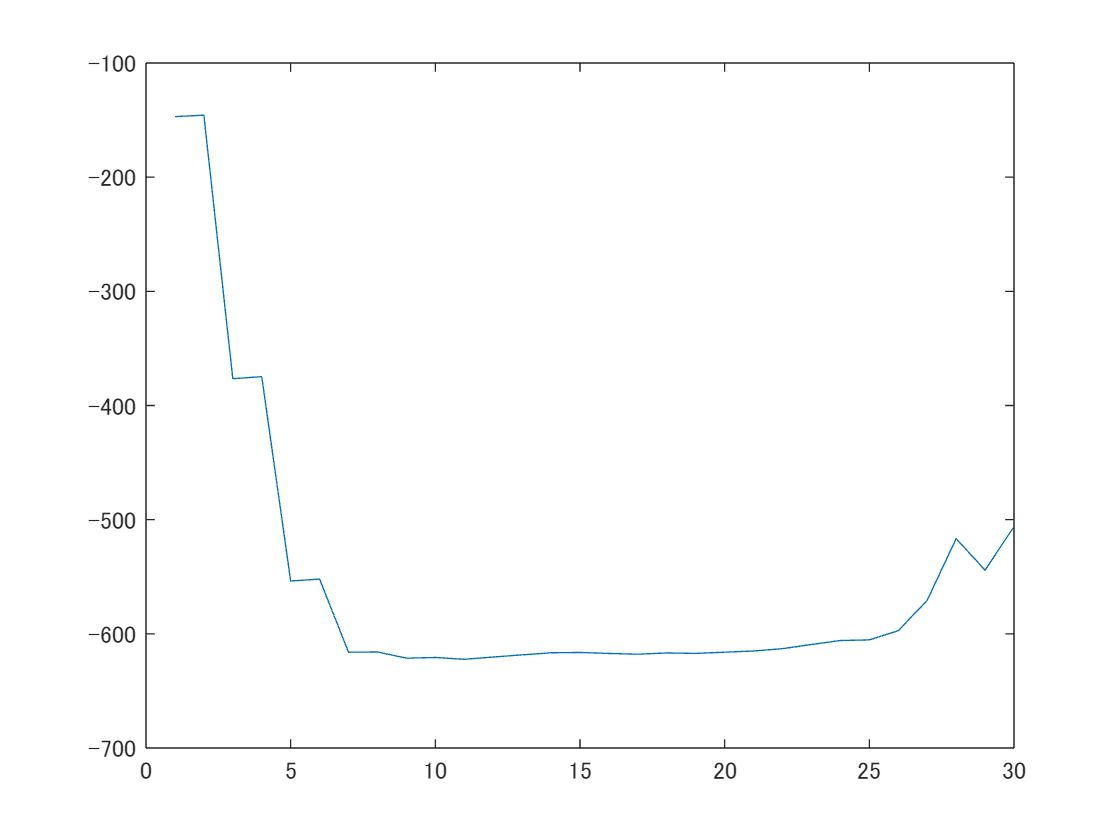


% # AICのプロット
figure
plot(1:maxdeg,aic)

drawnow

% 最小のAICを与える次数
[~,degopt] = min(aic);

% 多項式単回帰のインスタンス生成
regpopt = regp{degopt};
% 推定結果
beta0 = regpopt(end);
fprintf("β0 = %5.2f\n",beta0)

β0 = -0.02


for idx = 0:degopt-1
    beta = regpopt(degopt-idx);
    fprintf("β%d = %5.2f\n",idx+1,beta)
end

β1 =  0.28
β2 = 24.40
β3 = -637.49
β4 = 6627.30
β5 = -37222.28
β6 = 124367.63
β7 = -257054.66
β8 = 331694.58
β9 = -260371.44
β10 = 113876.57
β11 = -21303.92


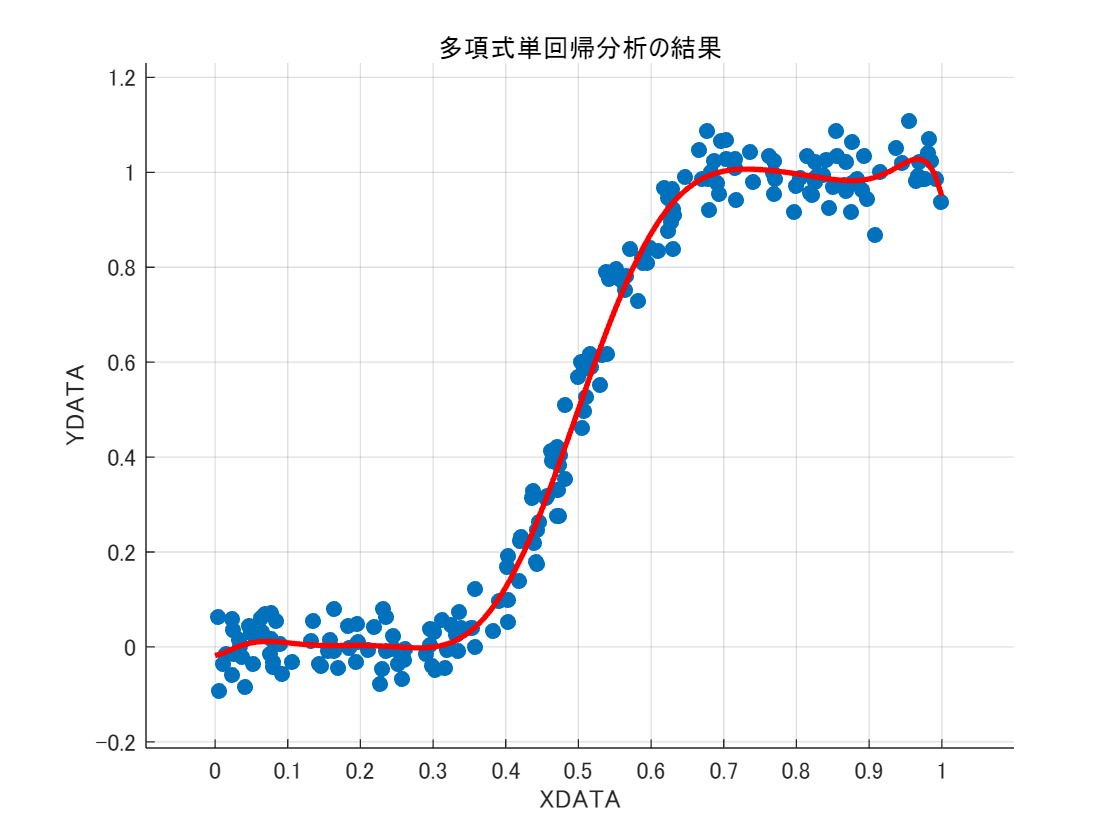

% 回帰曲線をプロット
figure
ax = gca;
xfit = 0:0.01:1;
yfit = polyval(regpopt,xfit);
scatter(x,y,'filled')
hold on
plot(xfit,yfit, 'r','LineWidth',2)
hold off
title("多項式単回帰分析の結果")
xlabel(dataset.Properties.VariableNames{1})
ylabel(dataset.Properties.VariableNames{2})
ax.XLim = [minx-0.1*rx,maxx+0.1*rx];
ax.YLim = [miny-0.1*ry,maxy+0.1*ry];
grid on

drawnow